U=[8.64,7.86,7.18,6.63,6.14,5.65,5.21,4.87,4.5,4.09,3.79,3.49,3.22,2.96,2.68,2.41,2.19,1.97,1.75,1.55,1.35,1.16,0.96,0.79,0.61,0.43,0.27];
r=1.2:0.2:6.4;
rr=1.2:0.01:6.4;
rrr=rr.^(-2);
UU=interp1(r,U,rr,"cubic")

UU =     8.6400    8.5986    8.5575    8.5166    8.4760    8.4356    8.3955    8.3556    8.3160    8.2766    8.2375    8.1986    8.1600    8.1216    8.0835    8.0456    8.0080    7.9706    7.9335    7.8966    7.8600    7.8236    7.7874    7.7513    7.7155    7.6799    7.6446    7.6094    7.5746    7.5400    7.5056    7.4716    7.4378    7.4044    7.3713    7.3385    7.3061    7.2740    7.2423    7.2109    7.1800    7.1495    7.1195    7.0899    7.0607    7.0320    7.0036    6.9755    6.9478    6.9203


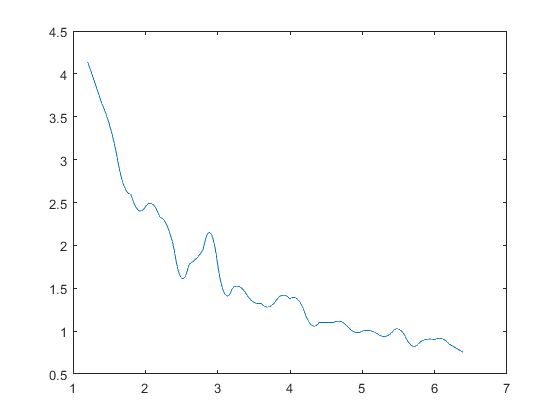

data=zeros(1,length(UU));
for i=1:length(UU)
    if i==1
        data(i)=(UU(i)-UU(i+1))/0.01;
    elseif i==length(UU)
        data(i)=(UU(i-1)-UU(i))/0.01;
    else
        data(i)=(UU(i-1)-UU(i+1))/0.02;
    end
end
plot(rr,data)